# Airframe Model - Environmental Forces

## Topic

This LiveScript continues with the development of your lesson on Airframes and includes the introduction of environmental forces that impact the flight of your UAV.

## Motivation

Eventually, you will need to consider all of the forces which impact your UAV flight dynamics.   In this module you will gather together a couple of forces that result from the world around the UAV.  One you you have used before:  gravity.  The other is wind drag which creates the first non-linearity to your model.   At this point your UAV is still modeled as a point mass but you will begin to specify parameters that will transition it to something more complex and useful.

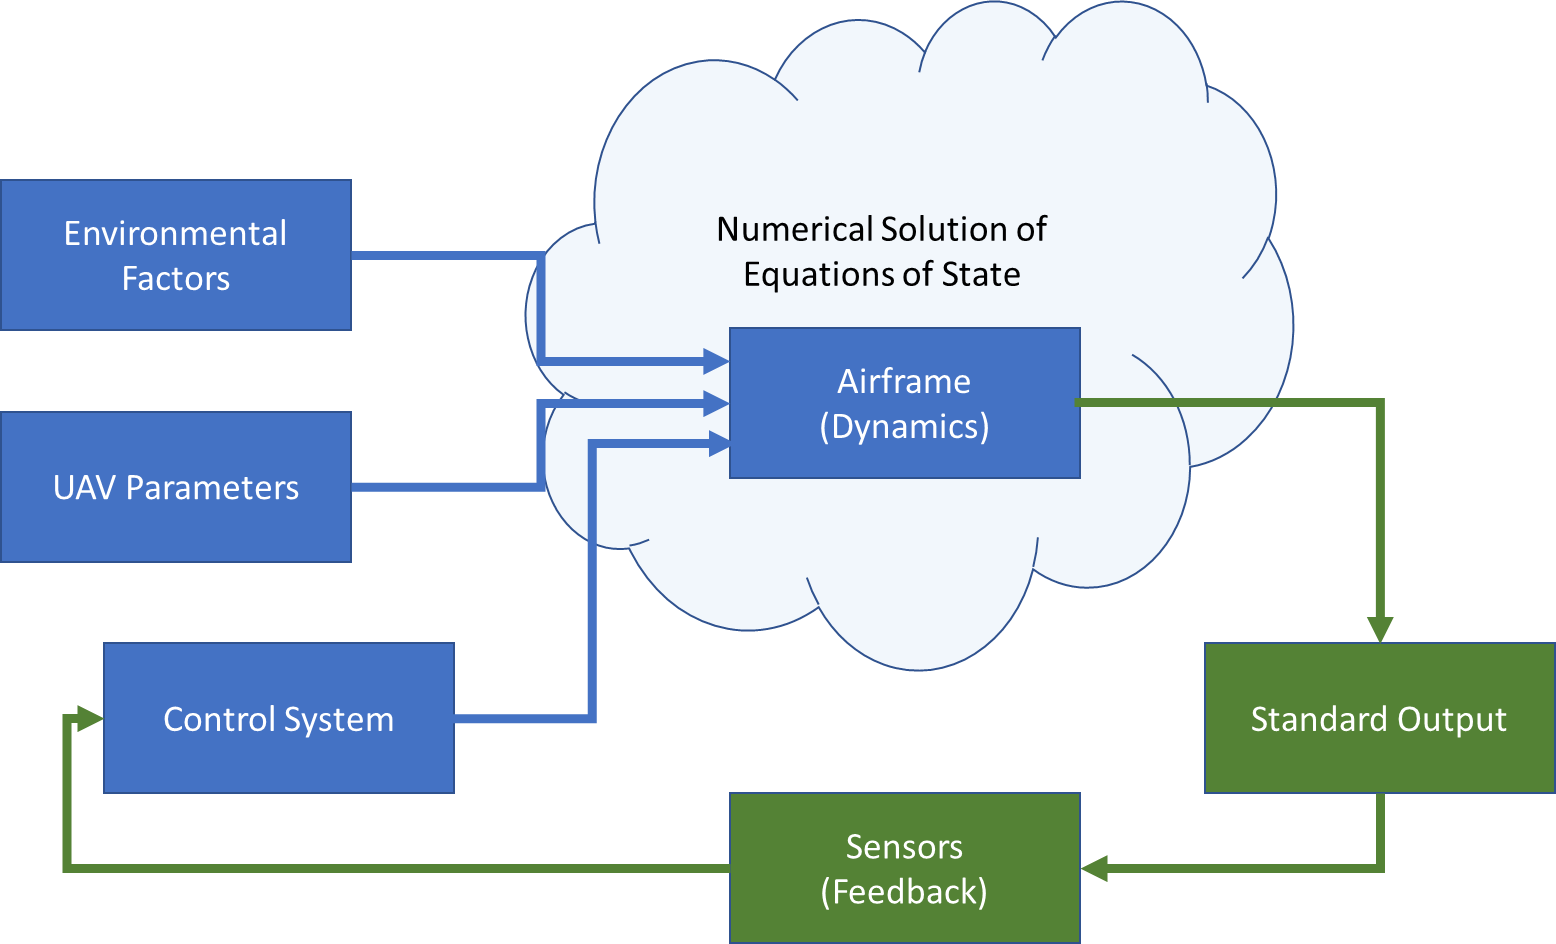

Key environmental factors include gravity and drag.

## Learning Objective

In this lesson you will go through the first steps of the development of the environmental factors that impact the flight of the UAV.    You will consider the equations of motion subject to both gravit and drag.   You will formulte and solve the resulting set of state equations.

## Lesson

### Utilities Used in Lesson

clear;
addpath('utils');

#### Previously

In your previous modules, you constructed a state-space model of a projectile flying through space.   Thus far the only force you have applied is gravity $F_{\textrm{gravity}} =-m\;g\;\hat{a_z }$.

$\frac{d}{\mathrm{d}t}\left\lbrack \begin{array}{c}
x\left(t\right)\\
y\left(t\right)\\
z\left(t\right)\\
v_x \left(t\right)\\
v_y \left(t\right)\\
v_z \left(t\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccccc}
0 & 0 & 0 & 1 & 0 & 0\\
0 & 0 & 0 & 0 & 1 & 0\\
0 & 0 & 0 & 0 & 0 & 1\\
0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\left(t\right)\\
y\left(t\right)\\
z\left(t\right)\\
v_x \left(t\right)\\
v_y \left(t\right)\\
v_z \left(t\right)
\end{array}\right\rbrack +\frac{1}{m}\left\lbrace \left\lbrack \begin{array}{c}
0\\
0\\
0\\
0\\
0\\
-\textrm{mg}
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0\\
0\\
0\\
F_x \\
F_y \\
F_z 
\end{array}\right\rbrack \right\rbrace$with  $\left\lbrack \begin{array}{c}
x\left(0\right)\\
y\left(0\right)\\
z\left(0\right)\\
v_x \left(0\right)\\
v_y \left(0\right)\\
v_z \left(0\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
x_0 \\
y_0 \\
z_0 \\
v_{\textrm{x0}} \\
v_{\textrm{y0}} \\
v_{\textrm{z0}} 
\end{array}\right\rbrack$

The input and output are:

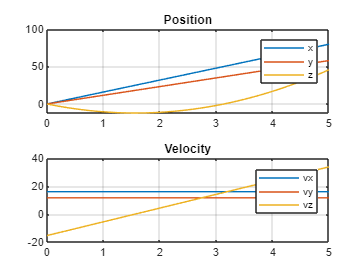

phid    =   36;    % angle from -90 to +90 degrees
thetad  = 128  ;       % angle from 0 to +180 degrees
v0      =  25;         % initial velocity (m/s)
tmax    =  5;         % duration of flight

tspan=[0,tmax];theta=pi*thetad/180;  phi=pi*phid/180;

[~,fxyz,mxyz,kd,zdesired,kp,kv,ff]=initializeParameters;
X0=[0;0;0]; V0=[v0*sin(theta)*cos(phi);v0*sin(theta)*sin(phi);v0*cos(theta)];
w0=[X0;V0;zeros(6,1)];

systemDerivative=@(t,w)dwdt(t,w,mxyz,fxyz,kd,ff,kp,kv,zdesired);

[ts,ws]=ode45(systemDerivative,tspan,w0); 
parametric_output3dof(ts,ws)

### Lesson A:  Adding Drag to the Equations of Motion

In the above example, the only force acting on the projectile was gravity.   The next force that you can describe in this inertial coordinate system is the drag force, which is proportional to the square of the velocity of your projectile.   If you continue with the formulation you already have, you need only to modify a couple of the equations.

**Drag Force**

The drag force is proportional to the velocity of the projectile and pointed in opposition to the velocity.   This can be written as $F={-k}_d v^2 {\hat{a} }_v$  , where the vector ${\hat{a} }_v$ represents the unit vector in the direction of the velocity of the mass.  This is a general expression and it indicates that the force has components in each cartesian direction, but that the magnitude is a result of the velocity of the components in aggregate.  This makes the term nonlinear.   The program of the solution will therefore need to couple the differential equations describing the motion in each of the cartesian directions.   How can you program this drag force?

### Exercise

Before you take on the full nonlinear problem, consider the case where the motion was limited to the z-direction.    As in a prior module, for this case, you have

  $\frac{\mathrm{d}}{\mathrm{d}t}\left\lbrack \begin{array}{c}
z\\
v_z 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
0 & 1\\
0 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
z\\
v_z 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0\\
g
\end{array}\right\rbrack$     and $Z\left(0\right)=\left\lbrack \begin{array}{c}
z_0 \\
v_{z,0} 
\end{array}\right\rbrack$

If you want to add additional forces, they need to go along with the gravity forces


$$\frac{\mathrm{d}}{\mathrm{d}t}\left\lbrack \begin{array}{c}
z\\
v_z 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
0 & 1\\
0 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
z\\
v_z 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0\\
g
\end{array}\right\rbrack +\frac{1}{m}\left\lbrack \begin{array}{c}
0\\
F_z 
\end{array}\right\rbrack$$


A program has been prepared with the solution of this simplified case.   

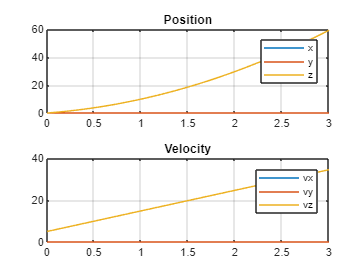

clear;
addpath('utils');
params=sys_params;

z0=0;     % initial position (m)
vz0= 5;    % initial velocity (m/s)
t_final=3; % simulation duration (sec)


% Solution illustrated 

[~,fxyz,mxyz,kd,zdesired,kp,kv,ff]=initializeParameters;
tspan=[0,t_final];
X0=[0;0;z0]; V0=[0;0;vz0];
w0=[X0;V0;zeros(6,1)];

systemDerivative=@(t,w)dwdt(t,w,mxyz,fxyz,kd,ff,kp,kv,zdesired);

[ts,ws]=ode45(systemDerivative,tspan,w0); 
parametric_output3dof(ts,ws)

**General Incorporation of Drag Force into the State Equations of Motion**

The drag force equation shows that the drag force $F={-k}_d v^2 {\hat{a} }_v$   is proportional to the velocity of the projectile and pointed in opposition to the velocity.   You need to take some care to get the correct vector orientation of the force.   As you may have determined in the example above, one way to do this is to take the squared velocity term and replace it.   $v^2 {\hat{a} }_v =v\left|v\right|$.    This observation leads to the realization that the drag force can be written:

$F={-k}_d v\left\lbrack \begin{array}{c}
v_x \\
v_y \\
v_z 
\end{array}\right\rbrack$   where $v=\sqrt{{\left\lbrack \begin{array}{c}
v_x \\
v_y \\
v_z 
\end{array}\right\rbrack }^T \left\lbrack \begin{array}{c}
v_x \\
v_y \\
v_z 
\end{array}\right\rbrack }$

After including drag into your model, you have a coupled nonlinear system of equations, as now the velocity in any direction impacts the position and velocity in every direction.  This is very difficult to analyze without a computer, but it remains one which is easily solved using numerical techniques such as those found in MATLAB.  Your nonlinear system becomes

$\frac{d}{\mathrm{d}t}\left\lbrack \begin{array}{c}
x\left(t\right)\\
y\left(t\right)\\
z\left(t\right)\\
v_x \left(t\right)\\
v_y \left(t\right)\\
v_z \left(t\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccccc}
0 & 0 & 0 & 1 & 0 & 0\\
0 & 0 & 0 & 0 & 1 & 0\\
0 & 0 & 0 & 0 & 0 & 1\\
0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\left(t\right)\\
y\left(t\right)\\
z\left(t\right)\\
v_x \left(t\right)\\
v_y \left(t\right)\\
v_z \left(t\right)
\end{array}\right\rbrack +\frac{1}{m}\left\lbrace \left\lbrack \begin{array}{c}
0\\
0\\
0\\
0\\
0\\
-\textrm{mg}
\end{array}\right\rbrack -k_d \sqrt{{\left\lbrack \begin{array}{c}
v_x \\
v_y \\
v_z 
\end{array}\right\rbrack }^T \left\lbrack \begin{array}{c}
v_x \\
v_y \\
v_z 
\end{array}\right\rbrack }\left\lbrack \begin{array}{c}
0\\
0\\
0\\
v_x \\
v_y \\
v_z 
\end{array}\right\rbrack \right\rbrace$    with     $\left\lbrack \begin{array}{c}
x\left(0\right)\\
y\left(0\right)\\
z\left(0\right)\\
v_x \left(0\right)\\
v_y \left(0\right)\\
v_z \left(0\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
x_0 \\
y_0 \\
z_0 \\
v_{\textrm{x0}} \\
v_{\textrm{y0}} \\
v_{\textrm{z0}} 
\end{array}\right\rbrack$

The solution can be found by modifying the forces explicitly in the functions that you pass to **ode45()**.

In the code below, the drag constant is assumed to be $k_d \approx 0\ldotp 05$.   You can modify the external force term so that each component of the external force is a function of the velocity.   You can see that as the drag increases the distance the projectile travels in y decreases before it hits the earth (z=0).   If you can change the value of $k_d$ to see the impact of changing the drag force.

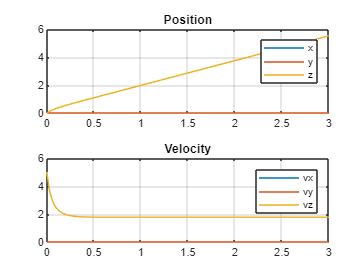


v0= 31;    % m/s
thetad=46;
phid=0;

theta=thetad*pi/180;  phi=phid*pi/180; 
                                
[~,fxyz,mxyz,~,zdesired,kp,kv,ff]=initializeParameters;

kd=0.2; % drag coefficient (1/meter)
tspan=[0,t_final];   Z0=[z0;vz0];
X0=[0;0;z0]; V0=[0;0;vz0];
w0=[X0;V0;zeros(6,1)];
m=params.mass;g=params.gravity;
systemDerivative=@(t,w)dwdt(t,w,mxyz,fxyz,kd,ff,kp,kv,zdesired);

[ts,ws]=ode45(systemDerivative,tspan,w0); 
parametric_output3dof(ts,ws)

### Conclusion

It this lesson you learned how to add drag to your simple flight model.   Now you have both gravity and drag, which are the two key environmental forces you will carry through as your model develops in complexity.

### Exercises:

Using the program above, can you find a value of drag for the given set of parameters $\left(v_0 \;,\theta \;,\phi \right)$, where the mass hits the ground, $z=0$, at $t=1\ldotp 6$ seconds?   What are the corresponding values of $x$ and $y$ ?

Does the mass go farther if you set drag to zero?  (Why or why not?)

Given a set of initial conditions, can you plot the resulting state traces with and without drag, so that you can see the difference?

% Your code goes here:






### Exercise:

Write your own flight function  $\frac{\mathrm{d}}{\mathrm{d}t}Z\left(t\right)=F\left(t,Z\right)$ that incorporates drag.

% Your code goes here:






**Exercise:**

Your task is to replicate the results of this program,the case of flight restricted to altitude motion only, with one of your own but add a drag force so that

$F={-k}_d v_z^2 {\hat{a} }_z$  .

To do this, your state-space system needs to be:


$$\frac{\mathrm{d}}{\mathrm{d}t}\left\lbrack \begin{array}{c}
z\\
v_z 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
0 & 1\\
0 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
z\\
v_z 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
0\\
-g
\end{array}\right\rbrack +\frac{1}{m}\left\lbrack \begin{array}{c}
0\\
{-k}_d v_z^2 
\end{array}\right\rbrack$$


% write your code here





### Your Subfunctions

% Your code for any required subfunctions goes here:




